Here is a matrix with both lower and upper bandwidth equal to one. Such a matrix is called tridiagonal.

A = [ 2 -1  0  0  0  0
      4  2 -1  0  0  0
      0  3  0 -1  0  0
      0  0  2  2 -1  0
      0  0  0  1  1 -1
      0  0  0  0  0  2 ]

A =      2    -1     0     0     0     0
     4     2    -1     0     0     0
     0     3     0    -1     0     0
     0     0     2     2    -1     0
     0     0     0     1     1    -1
     0     0     0     0     0     2


We can extract the elements on any diagonal using the `diag` command. The "main'' or central diagonal is numbered zero, above and to the right of that is positive, and below and to the left is negative.

diag_main = diag(A,0)'

diag_main =      2     2     0     2     1     2


diag_plusone = diag(A,1)'

diag_plusone =     -1    -1    -1    -1    -1


diag_minusone = diag(A,-1)'

diag_minusone =      4     3     2     1     0


We can also put whatever numbers we like onto any diagonal with the `diag` command.

A = A + diag([5 8 6 7],2)

A =      2    -1     5     0     0     0
     4     2    -1     8     0     0
     0     3     0    -1     6     0
     0     0     2     2    -1     7
     0     0     0     1     1    -1
     0     0     0     0     0     2


Here is what happens when we factor this matrix without pivoting. 

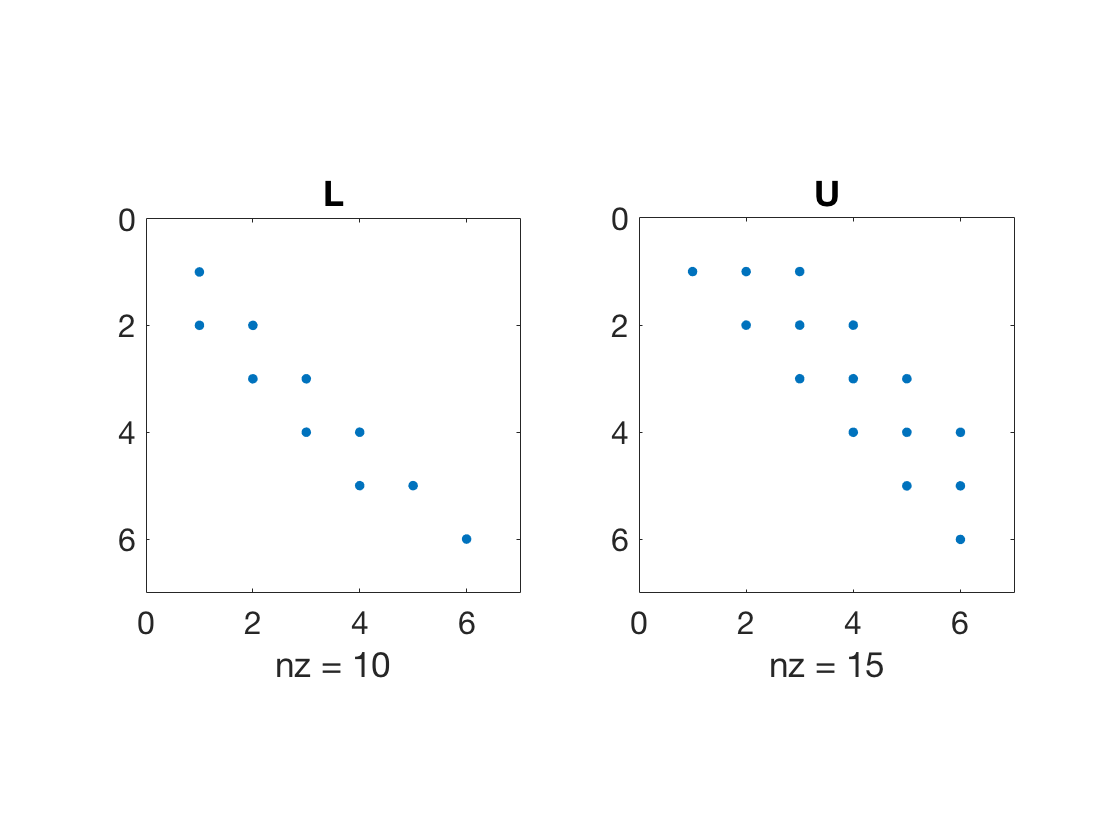

[L,U] = lufact(A);
subplot(1,2,1), spy(L), title('L')
subplot(1,2,2), spy(U), title('U')

Observe that the factors preserve the lower and upper bandwidth of the original matrix. However, if we introduce row pivoting, this structure may be destroyed.

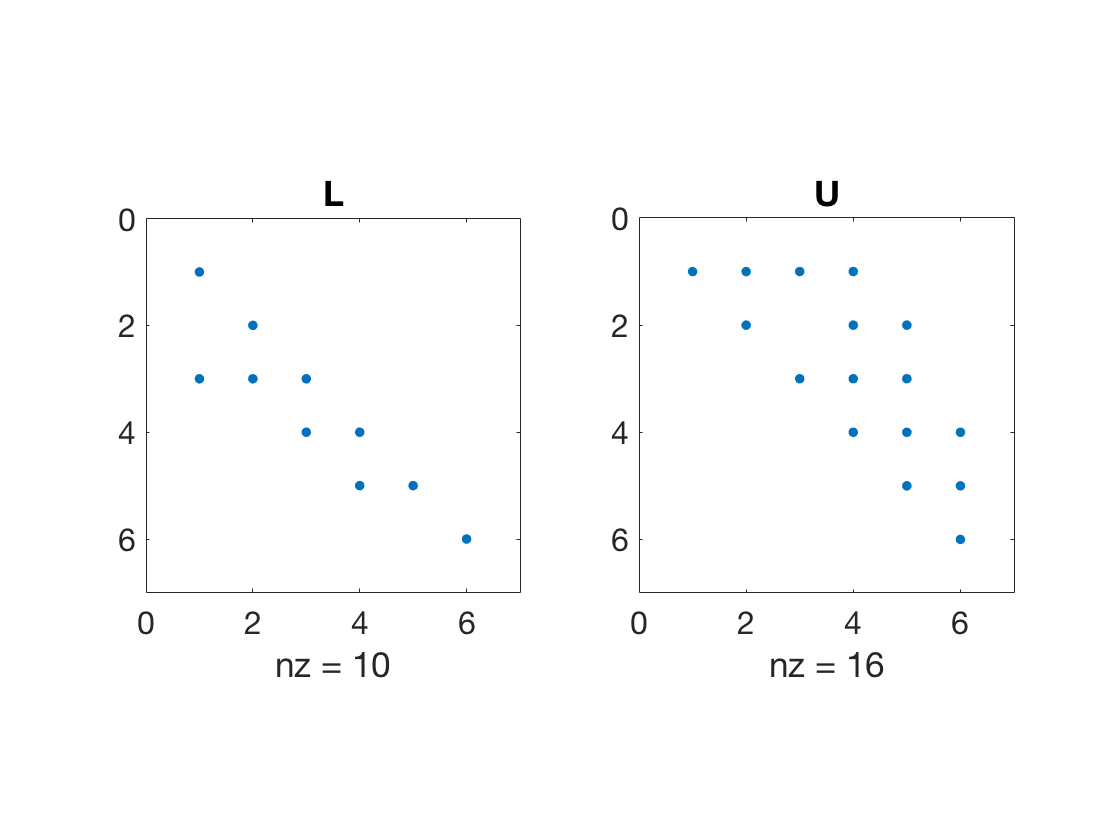

[L,U,P] = lu(A);
subplot(1,2,1), spy(L), title('L')
subplot(1,2,2), spy(U), title('U')